
for x = 1:20
    y = get_parts(x);
    disp(num2str(x) + ": " +  num2str(y))
end


y = get_parts(12)

y =    984   975   921   876   831   741   732   651   642   543   192   183   174   165   111    93    84    75    21    12


disp(y)

  Columns 1 through 7

   984   975   921   876   831   741   732

  Columns 8 through 14

   651   642   543   192   183   174   165

  Columns 15 through 20

   111    93    84    75    21    12



is_decreasing( 695 )

x = [0, 1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11, 12, 13, 14, 15, 16, 17, 18, 19, 20, 21, 22, 23, 24, 25, 26, 27, 28, 29, 30, 31, 32, 33, 34, 35, 36, 37, 38, 39, 40, 41, 42, 43, 44, 45, 46, 47, 48, 49, 50, 51, 52, 53, 54, 55, 56, 57, 58, 59]

x =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


y = [0, 0, 0, 1, 1, 2, 3, 4, 5, 7, 9, 11, 14, 17, 21, 26, 31, 37, 45, 53, 63, 75, 88, 103, 121, 141, 164, 191, 221, 255, 295, 339, 389, 447, 511, 584, 667, 759, 863, 981, 1112, 1259, 1425, 1609, 1815, 2047, 2303, 2589, 2909, 3263, 3657, 4096, 4581, 5119, 5717, 6377, 7107, 7916, 8807, 9791]

y =            0           0           0           1           1           2           3           4           5           7           9          11          14          17          21          26          31          37          45          53          63          75          88         103         121         141         164         191         221         255         295         339         389         447         511         584         667         759         863         981        1112        1259        1425        1609        1815        2047        2303        2589        2909        3263


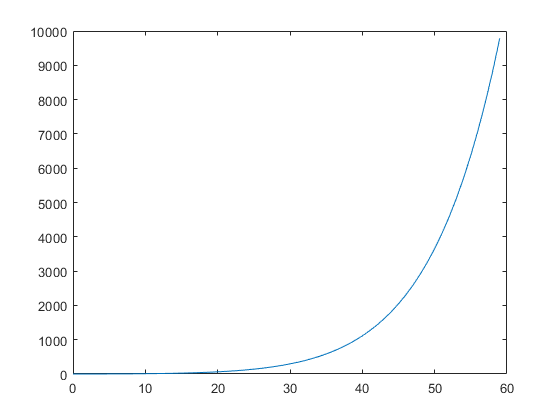

plot(x,y)

[f,gof] = fit(x',y',"poly2")

f =      Linear model Poly2:
     f(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =       4.911  (4.257, 5.565)
       p2 =      -179.4  (-219.3, -139.5)
       p3 =        1064  (554.5, 1573)

gof = struct with fields:
           sse: 2.6231e+07
       rsquare: 0.9249
           dfe: 57
    adjrsquare: 0.9223
          rmse: 678.3755


feval(f,200)

ans = 1.6162e+05

%% Setup the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 5);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = " ";

% Specify column names and types
opts.VariableNames = ["n", "Var2", "l", "Var4", "t"];
opts.SelectedVariableNames = ["n", "l", "t"];
opts.VariableTypes = ["double", "string", "double", "string", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
opts.ConsecutiveDelimitersRule = "join";
opts.LeadingDelimitersRule = "ignore";

% Specify variable properties
opts = setvaropts(opts, ["Var2", "Var4"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var2", "Var4"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, ["n", "l"], "TrimNonNumeric", true);
opts = setvaropts(opts, ["n", "l"], "ThousandsSeparator", ",");

% Import the data
data = readtable("C:\Users\Ciaran\Documents\GitHub\covid-19-analysis\data.txt", opts);


x = data.n;
y = data.t;
figure; axes('NextPlot','add');
plot(x,seconds(y),'LineWidth',2)
[f,gof] = fit(x,y,"exp1")

f =      General model Exp1:
     f(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =    0.001014  (0.0008516, 0.001177)
       b =     0.06605  (0.06514, 0.06697)

gof = struct with fields:
           sse: 518.4866
       rsquare: 0.9975
           dfe: 182
    adjrsquare: 0.9974
          rmse: 1.6878


Ln = feval(f,200)

Ln = 554.0843

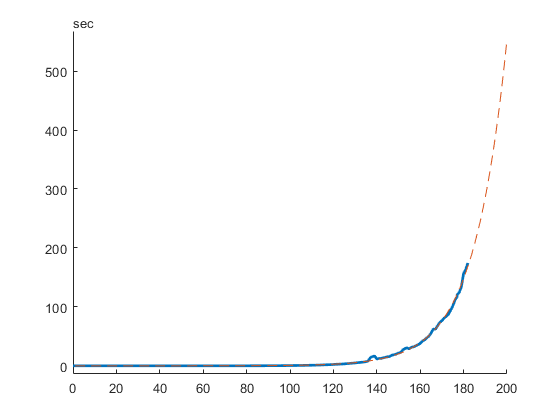

xn = 1:200;
plot(xn,seconds(feval(f,xn)),'--');

seconds(feval(f,200))

ans = duration
   554.08 sec


for i = 1:height(data)
a = data.n(i); b = data.l(i);
disp([num2str(a,'%.0f') ':' num2str(b,'%.0f') ','])
end

0:0,
1:0,
2:0,
3:1,
4:1,
5:2,
6:3,
7:4,
8:5,
9:7,
10:9,
11:11,
12:14,
13:17,
14:21,
15:26,
16:31,
17:37,
18:45,
19:53,
20:63,
21:75,
22:88,
23:103,
24:121,
25:141,
26:164,
27:191,
28:221,
29:255,
30:295,
31:339,
32:389,
33:447,
34:511,
35:584,
36:667,
37:759,
38:863,
39:981,
40:1112,
41:1259,
42:1425,
43:1609,
44:1815,
45:2047,
46:2303,
47:2589,
48:2909,
49:3263,
50:3657,
51:4096,
52:4581,
53:5119,
54:5717,
55:6377,
56:7107,
57:7916,
58:8807,
59:9791,
60:10879,
61:12075,
62:13393,
63:14847,
64:16443,
65:18199,
66:20131,
67:22249,
68:24575,
69:27129,
70:29926,
71:32991,
72:36351,
73:40025,
74:44045,
75:48445,
76:53249,
77:58498,
78:64233,
79:70487,
80:77311,
81:84755,
82:92863,
83:101697,
84:111321,
85:121791,
86:133183,
87:145577,
88:159045,
89:173681,
90:189585,
91:206847,
92:225584,
93:245919,
94:267967,
95:291873,
96:317787,
97:345855,
98:376255,
99:409173,
100:444792,
101:483329,
102:525015,
103:570077,
104:618783,
105:671417,
106:728259,
107:789639,
108:855905,
109:927405,
110:100


x = data.n;
y = data.l;
figure; axes('NextPlot','add');
plot(x,y,'LineWidth',2)
[f,gof] = fit(x,y,"exp1")

f =      General model Exp1:
     f(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =       887.4  (854.7, 920.1)
       b =     0.06664  (0.06643, 0.06686)

gof = struct with fields:
           sse: 1.3235e+13
       rsquare: 0.9999
           dfe: 176
    adjrsquare: 0.9999
          rmse: 2.7423e+05


Ln = feval(f,200)

Ln = 5.4531e+08

expected = 487067745;
error = sprintf( '%.2f%%', 100*((Ln-expected) / expected) )

error = '11.96%'

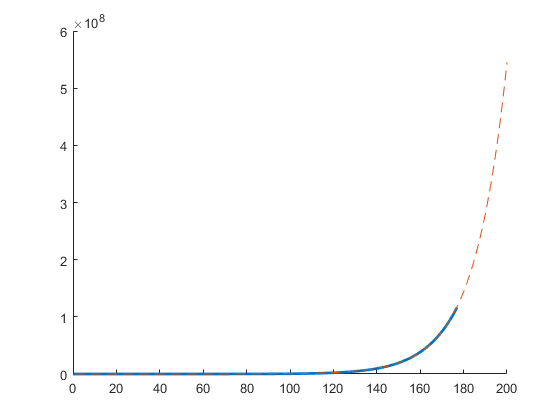

xn = 1:200;
plot(xn,feval(f,xn),'--');

s = sprintf('%.0f', Ln);
for i = length(s)-3:-3:1
    s = [s(1:i) ',' s(i+1:end)];
end
s

s = '545,305,986'

function y = get_parts(x)

y = generate_sequence(x);

if isempty(y); return; end


for xi = y
    yi = generate_sequence(xi);
    yi = setdiff(yi,y);
    if ~isempty(yi)
        yi = remove_invalid(yi);
        y = [y yi];
    end
end

y = remove_invalid(y);
y = unique(y);
y = sort(y,'desc');

end

function y = generate_sequence(x)

y = 10*x - 9;
a = y;
while a>0
    a = a - 9;
    y(end+1) = a;
end
end

function y = remove_invalid(x)

y = x;
y = y(y>11);

f = @(x,n) floor(x/10) == x/n;
y = y(~arrayfun( @(x) f(x,11), y ));
y = y(~arrayfun( @(x) f(x,10), y ));

y = y( arrayfun( @is_decreasing, y));

y = [x(1) y];


end

function tf = is_decreasing(x)
a = x;
b = [];
while a>1
    b = [rem(a,10) b];
    a = floor(a/10);
end
tf = all(diff(b)<0);
end

function y = to_array(x)
m = floor(log10(x));
y = mod(floor(x ./ 10 .^ (m:-1:0)), 10);
end
